# Task 1) Using a for loop

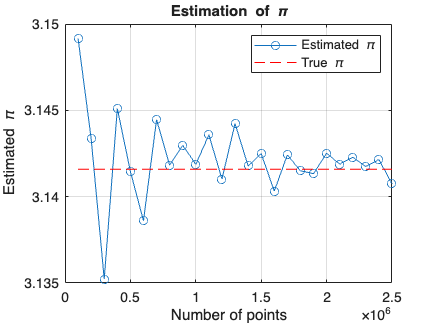

% We estimate pi for the fixed number of random points
% Define sample size
N = (1:25)*10^5;

% Pre-allocate arrays to store results for efficiency.
estimates = zeros(1,length(N));    % Estimated values of Pi
deviations = zeros(1,length(N));   % Deviations from true Pi
execution_times = zeros(1,length(N)); % Execution times

% Loop over different sample sizes
for k = 1:length(N)
    num_points = N(k);    % number of random points for this trial
    
    % Generate random points in the first quadrant.
    x = rand(1,num_points);
    y = rand(1,num_points);
    
    % Initialized counter for points inside the quarter circle
    in_circle = 0;
    
    % Start timing the execution for the current sample size
    tic;

    % Loop over all points and check if they are inside the quarter circle
    for i = 1:num_points
        if x(i)^2 + y(i)^2 <= 1
            in_circle = in_circle + 1;
        end
    end
    
    % Record elapsed time for this trial
    execution_time = toc;

    % Compute estimate of pi
    estimate_pi = 4*in_circle/num_points;

    % Compute deviation
    deviation = abs(pi-estimate_pi);
    
    % Store results in arrays
    estimates(k) = estimate_pi;
    deviations(k) = deviation;
    execution_times(k) = execution_time;
end

% Plot the estimates of Pi for each sample size
figure;
plot(N, estimates, '-o', 'DisplayName', 'Estimated \pi');
hold on;
plot(N, pi*ones(size(N)), 'r--', 'DisplayName', 'True \pi');
xlabel('Number of points');
ylabel('Estimated \pi');
title('Estimation of \pi');
legend show;
grid on;

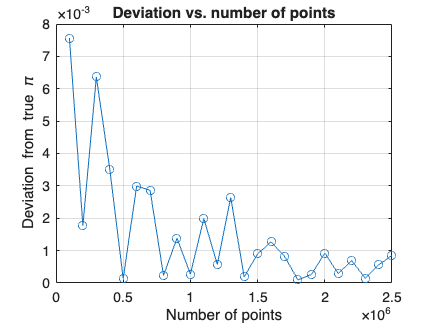


% Plot deviations for each sample size
figure;
plot(N, deviations, '-o');
xlabel('Number of points');
ylabel('Deviation from true \pi');
title('Deviation vs. number of points');
grid on;

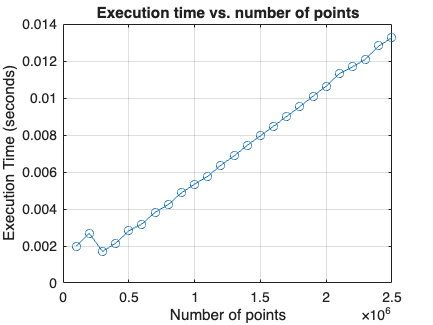


% Plot execution time
figure;
plot(N, execution_times, '-o');
xlabel('Number of points');
ylabel('Execution Time (seconds)');
title('Execution time vs. number of points');
grid on;

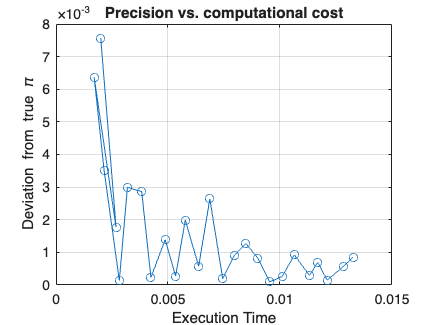


% Comparing precesion to the computational cost
figure;
plot(execution_times, deviations, '-o');
xlabel('Execution Time');
ylabel('Deviation from true \pi');
title('Precision vs. computational cost');
grid on;

## Task 2) Using a while loop

% --- Initialization ---
in_circle = 0;     % Number of points lie in a unit circle
num_points = 0;    % Number of points generated
sig_fig = 4;       % Desired significant figure
tolerance_counter = 0;   % tolerance counter for stability
required_stable_iterations = 10^6;

% Initialized estimates.
prev_estimate = 0;
last_estimate = 4;

while tolerance_counter < required_stable_iterations
    % Generate a single random point in the first quadrant.
    x = rand;
    y = rand;

    % Increment total number of points.
    num_points = num_points + 1;
    
    % Check if the point is inside the unit circle.
    if x^2+y^2 <= 1
        in_circle = in_circle + 1;
    end
    

    % Calculate the new estimate for pi.
    last_estimate = 4*in_circle / num_points; % in_squre never be 0.
    
    % Stability check
    if abs(prev_estimate-last_estimate)< 10^(-sig_fig+1)
        tolerance_counter = tolerance_counter + 1;
    else
        tolerance_counter = 0;
    
    % Update the previous estimate with hte last estimate.
    prev_estimate = last_estimate;

    end
end

% --- Final Output ---
fprintf('Desired significant figure: %d\n',sig_fig);

Desired significant figure: 4


fprintf('Total points generated: %d\n', num_points)

Total points generated: 4171798


fprintf('Final estimated value of Pi: %f\n', last_estimate)

Final estimated value of Pi: 3.140126
